load load_to_test
Pload_base = str2double(to_try.power)';
t_base = str2double(to_try.time)';
DT = 1;
Ppv = 150;
Pfcnom = 800;

t = 0:DT:t_base(end);
Pload = fixpt_interp1(t_base,Pload_base,t,sfix(16),2^-3,sfix(16),...
 2^-2,'Floor');
Pload = Pload-Ppv;
Pload(Pload<0)=0;

Tp = t(end);
nb_points = length(t);
N = linspace(1,Tp,nb_points);
Pfc_min=250; Pfc_max=1100;
x0=Pfc_min*ones(1,length(N));
SOC0=80; SOC_min=50;
Q=15*13.5; Vbatt_nom=48;

%defining matrix A
A=zeros(length(N),length(N));
Ab=zeros(length(N),length(N));
for i=1:length(N)
    for j=1:i
        A(i,j)=-DT;
        Ab(i,j)=1;
    end
end
%defining matrix b
b=zeros(length(N),1);
y=zeros(length(N),1);


y=Ab*Pload';
for i=1:length(N)
    b(i,1)=(SOC0-SOC_min)*Vbatt_nom*Q-y(i)*DT;
end

% add the energy constraint
%Fuel cell minimum energy s
Efc_min=sum(x0)*DT;
b(length(N),1)=-Efc_min;
lb=Pfc_min*ones(1,length(N));
ub=Pfc_max*ones(1,length(N));

options = optimoptions(@fmincon,'Algorithm', ...
    'sqp','MaxIterations',1000);
[x,fval] = fmincon(@myfun2,x0,A,b,[],[],lb,ub,[],options);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


SOC=SOC0-(A*x'+y)/(Vbatt_nom*Q);
fprintf('SOC init: %3.2f, SOC final: %3.2f',SOC(1),SOC(end));

SOC init: 80.03, SOC final: 50.16

ConsH2=fval*242/(Pfcnom*Tp);
fprintf('H2 consumption %5.3f',ConsH2);

H2 consumption 100.503

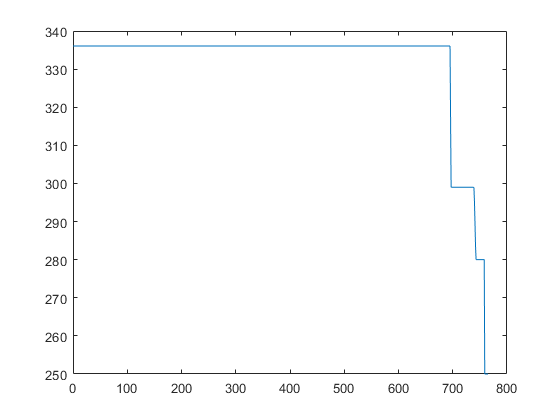

plot(t,x)

function f = myfun2(x)
DT=1;
f = sum(x)*DT;
end